# Week 9 Activity

### 1. Go to Google Earth or a similar map and look up the latitude and longitude at the intersection of Temple Street and Hope Street in Los Angeles. Report these geodetic coordinates. This site has VS30 = 376 m/s, Z1.0=0.32 km and Z2.5=2.7 km.

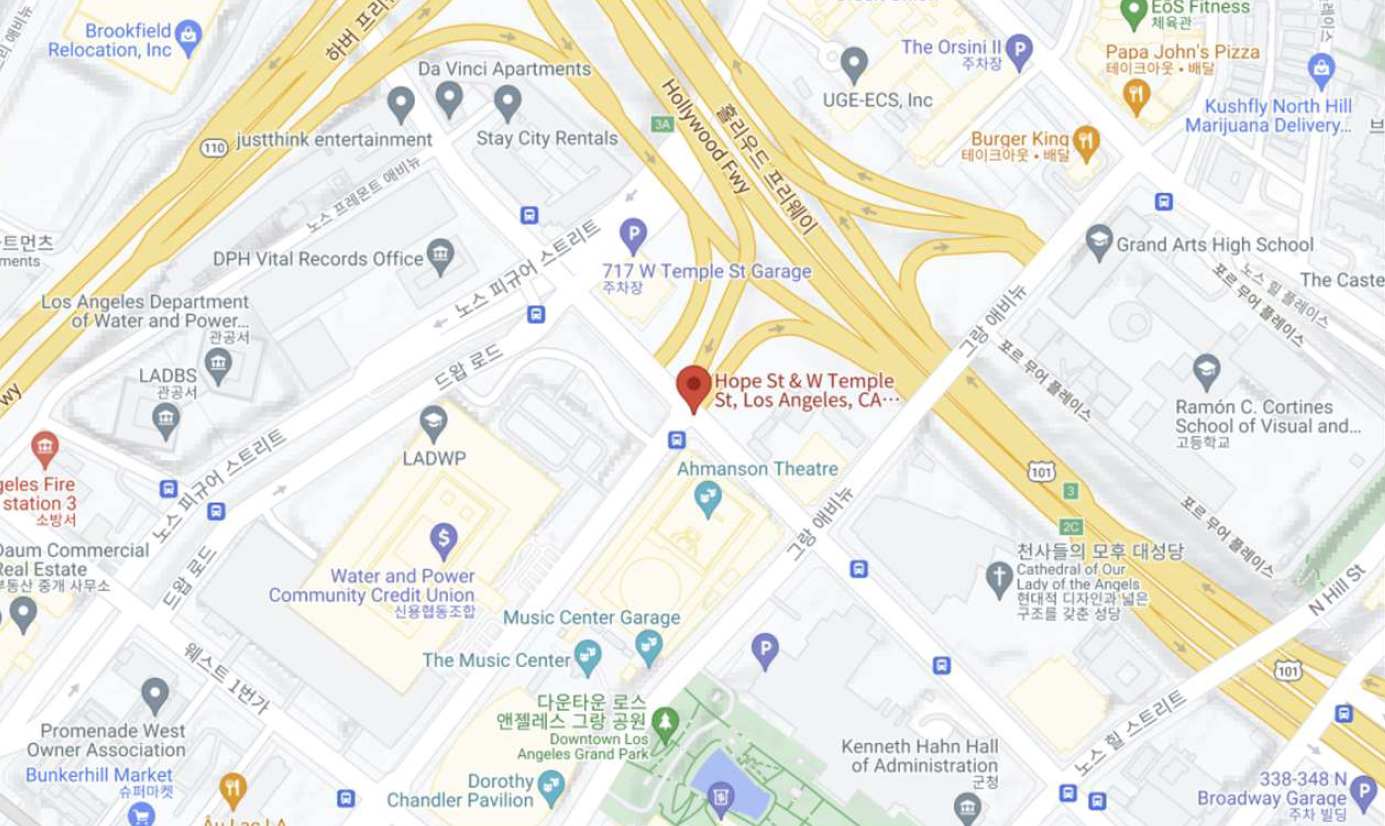

### 2. Using the OpenSHA hazard curve Java applet, develop hazard curves for 1.0 sec pseudo spectral acceleration using the mean UCERF3 source model and the four NGA West2 GMMs that include a site term (ASK14, BSSA14, CB14, CY14). Plot these hazard curves together in a single plot.

#### Data set of GMM x

x1 = [1.00E-04 ; 1.30E-04; 1.60E-04; 2.00E-04; 2.50E-04; 3.20E-04; 4.00E-04; 
    5.00E-04; 6.30E-04; 7.90E-04; 0.001; 0.00126; 0.00158; 0.002; 
    0.00251; 0.00316; 0.00398; 0.00501; 0.00631; 0.00794; 0.01; 0.01259; 
    0.01585; 0.01995; 0.02512; 0.03162; 0.03981; 0.05012; 0.0631; 0.07943; 
    0.1; 0.12589; 0.15849; 0.19953; 0.25119; 0.31623; 0.39811; 0.50119; 
    0.63096; 0.79433; 1; 1.25893; 1.58489; 1.99526; 2.51189; 3.16228; 
    3.98107; 5.01187; 6.30957; 7.94328; 10; ];

#### Data set of GMM Ask 14

y1 = [1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 0.99999994; 
    0.99999934; 0.999992; 0.9999324; 0.99958116; 0.9980463; 0.99290216;
    0.9793776; 0.950581; 0.899887; 0.82443327; 0.727537; 0.6176127; 
    0.50518143; 0.39906132; 0.30489266; 0.2252094; 0.16043003; 0.10980089;
    0.07188369; 0.044814814; 0.026493777; 0.014793656; 0.007772704; 
    0.00382887; 0.001762037; 7.55E-04; 3.00E-04; 1.10E-04; 3.75E-05; 
    1.17E-05; 3.38E-06; 8.95E-07; ];

#### Data set of GMM BSSA 14

y2 = [1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 0.9999998;
    0.99999744; 0.9999736; 0.9998031; 0.9989143; 0.9954339; 0.98498434;
    0.96014684; 0.912394; 0.83640033; 0.7342371; 0.6154696; 0.49364838;
    0.38075274; 0.28422567; 0.20655635; 0.1467092; 0.10193311; 6.91E-02;
    4.54E-02; 2.87E-02; 1.72E-02; 9.75E-03; 5.17E-03; 2.54E-03; 1.16E-03;
    4.83E-04; 1.85E-04; 6.46E-05; 2.06E-05; 5.96E-06; 1.57E-06; ];

#### Data set of GMM CB14

y3 = [1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 
    0.99999994; 0.9999984; 0.99997884; 0.9998114; 0.9988157; 
    0.9946136; 0.98151284; 0.9503614; 0.89192516; 0.8027928; 
    0.6886977; 0.5628531; 0.43982476; 0.33060685; 0.24057521;
    0.17030813; 0.1175675; 0.079052456; 0.051535998; 0.032337807;
    0.01936326; 0.010968982; 0.005833507; 0.002893586; 0.001331783;
    5.66E-04; 2.22E-04; 7.99E-05; 2.64E-05; 8.00E-06; 2.22E-06; ];

#### Data set of GMM CY14

y4 = [1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 
    0.9999994; 0.9999911; 0.9999113; 0.9993833; 0.9969084; 0.98848283;
    0.9667901; 0.9231982; 0.8524446; 0.756668; 0.6447722; 0.52866745;
    0.41858792; 0.32119069; 0.23946093; 0.17365299; 0.12239391;
    0.08355483; 0.05490142; 0.034425594; 0.020402808; 0.011321777;
    0.0058337; 0.002771618; 0.001207385; 4.80E-04; 1.74E-04; 
    5.70E-05; 1.69E-05; 4.54E-06; 1.10E-06; ];

#### Plot graph

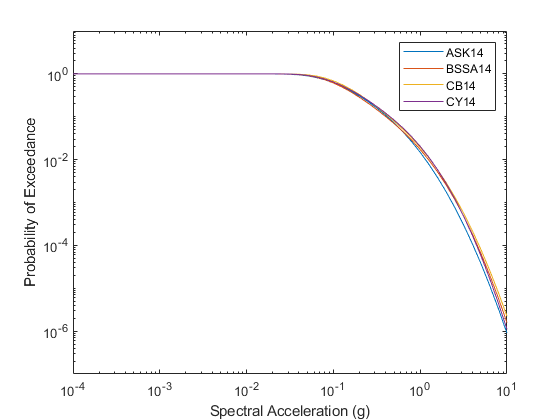

loglog(x1,y1,x1,y2,x1,y3,x1,y4)
xlim([0.0001 10])
ylim([10e-8 10])
xlabel('Spectral Acceleration (g)')
ylabel('Probability of Exceedance')
legend('ASK14',	'BSSA14','CB14','CY14')

### 3.Consider epistemic uncertainty in the GMM by calculating the mean hazard curves and its 95% confidence intervals. Add these results to your plot from (2).

#### Average of GMM data set

y5 = zeros(51,1);
for i= 1 : 1 : 51
    aver = (y1(i) + y2(i) + y3(i) + y4(i)) / 4 ;
    y5(i) = aver;
end

#### Plot graph

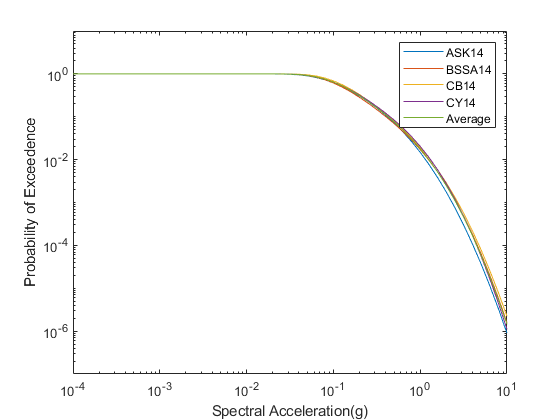

loglog(x1,y1,x1,y2,x1,y3,x1,y4,x1,y5)
xlim([0.0001 10])
ylim([10e-8 10])
ylabel('Probability of Exceedence')
xlabel('Spectral Acceleration(g)')
legend('ASK14',	'BSSA14','CB14','CY14','Average')

#### calculating the mean hazard curves and its 95% confidence intervals.


$${<\mu_x >}_{0\ldotp 95} =\left\lbrack \bar{x} \pm \;t_{p\;=0\ldotp 95,f=3} *\frac{\sigma_x }{\sqrt{n}}\right\rbrack$$


calculate $\frac{\sigma_x }{\sqrt{n}}$

sttdd = zeros(51,1);
for i= 1 : 1 : 51
    sttd = [y1(i), y2(i),  y3(i),  y4(i)];
    sttdd(i) = std(sttd)/2;
end


$$t_{p\;=0\ldotp 95,f=3}$$


t = 2.353;


$$\bar{x} +t_{p\;=0\ldotp 95,f=3} *\frac{\sigma_x }{\sqrt{n}}$$


y6 = zeros(51,1);
for i= 1 : 1 : 51
    y6(i) = y5(i) + t*sttdd(i);
end


$$\bar{x} -t_{p\;=0\ldotp 95,f=3} *\frac{\sigma_x }{\sqrt{n}}$$


y7 = zeros(51,1);
for i= 1 : 1 : 51
    y7(i) = y5(i) - t*sttdd(i);
end

#### Plot graph

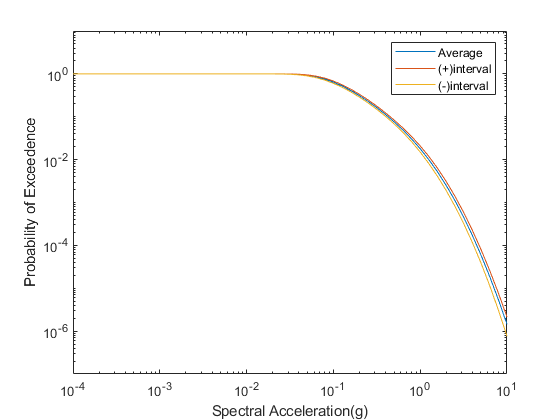

loglog(x1,y5,x1,y6,x1,y7)
xlim([0.0001 10])
ylim([10e-8 10])
ylabel('Probability of Exceedence')
xlabel('Spectral Acceleration(g)')
legend('Average','(+)interval','(-)interval')

### 4. Using the BSSA14 GMM, perform a disaggregation for the probability level corresponding to 2% probability of exceedance in 50 years for SA at 1.0 and 5.0 sec. What are the mean magnitudes, distances, and epsilons for these two cases? Which are the controlling faults?

#### T = 1.0  

    Disaggregation Results for Prob = 0.02 (for IML = 0.17761353) 

      Mbar = 7.6087375 

      Dbar = 21.946173 

      Ebar = 1.2580676 

      7.75 ≤ Mmode < 8.25

      50.0 ≤ Dmode < 60.0

      1.0 < Emode <= 2.0 

#### T = 5.0

    Disaggregation Results for Prob = 0.02 (for IML = 1.1555473)

      Mbar = 7.0517793

      Dbar = 9.991044

      Ebar = 1.2492446 

      6.25 ≤ Mmode < 6.75  

      0.0 ≤ Dmode < 10.0 

      1.0 < Emode <= 2.0 

### 5. Using the OpenSHA hazard spectrum Java applet, develop uniform hazard spectra for the four GMMs. Show also the mean spectrum and 95% confidence intervals in consideration of epistemic uncertainty. Plot all spectra on the same figure using log-log axes.

#### Data set of aks14

ask14x = [0.01; 0.02; 0.03; 0.05; 0.075; 0.1; 0.15; 0.2; 0.25; 0.3; 
    0.4; 0.5; 0.75; 1; 1.5; 2; 3; 4; 5; 6; 7.5; 10; ];
ask14y = [0.9475959; 0.95143634; 0.9333966; 1.0010262; 1.1936357; 
    1.4386282; 1.9755005; 2.4163144; 2.6602793; 2.732068; 2.4751089;
    2.0907419; 1.4366877; 1.0761372; 0.7046115; 0.4950722; 0.29736996;
    0.21108215; 0.16384436; 0.13513193; 0.10686417; 0.076060146; ];

#### Data set of aks14-twosided

ask14ty = [0.79682577; 0.7983998; 0.7786165; 0.8219933; 0.9797582; 
    1.1780269; 1.6185752; 2.010972; 2.2382061; 2.3257368; 2.1057901; 
    1.768983; 1.2116945; 0.9005546; 0.5867606; 0.41003224; 0.24826507; 
    0.17633414; 0.13707829; 0.11338616; 0.089988805; 0.064525835; ];

#### Data set of cb14

cb14x = [0.01; 0.02; 0.03; 0.05; 0.075; 0.1; 0.15; 0.2; 0.25; 0.3; 
    0.4; 0.5; 0.75; 1; 1.5; 2; 3; 4; 5; 7.5; 10; ];
cb14y = [0.75321805; 0.7758175; 0.844619; 1.0348433; 1.3093021; 
    1.505303; 1.6582663; 1.6955918; 1.7609165; 1.8700777; 1.8783886;
    1.7885325; 1.5123502; 1.2118988; 0.78346395; 0.5519147; 0.34943354;
    0.22945735; 0.16569412; 0.07633727; 0.040708333; ];

#### Data set of cb14-twosided

cb14ty = [0.6813444; 0.70119447; 0.7665483; 0.9269162; 1.14302;
    1.2976012; 1.4243844; 1.4677666; 1.5438503; 1.6287737; 1.6554313;
    1.5835184; 1.3213743; 1.0653296; 0.6866182; 0.48648775; 0.3049865;
    0.19960155; 0.1427253; 0.0655509; 0.034928787; ];

#### Data set of bssa14

bssa14x = [0.01; 0.02; 0.03; 0.05; 0.075; 0.1; 0.15; 0.2; 0.25; 0.3; 
    0.4; 0.5; 0.75; 1; 1.5; 2; 3; 4; 5; 7.5; 10; ];
bssa14y = [1.055397; 1.0518713; 1.1161739; 1.3909864; 1.8363576; 
    2.1617975; 2.4106646; 2.377457; 2.309729; 2.2645657; 2.0807598;
    1.9210143; 1.4646665; 1.1555473; 0.70854884; 0.4892181; 0.3076176;
    0.22516403; 0.17761353; 0.1097209; 0.06868918; ];

#### Data set of bssa14-twosided

bssa14ty = [0.9128473; 0.90921885; 0.9549469; 1.1508161; 1.4923992; 
    1.7685138; 2.0583222; 2.0953524; 2.0709822; 2.0516772; 1.8867474;
    1.7290598; 1.3114982; 1.0347885; 0.6337789; 0.43075815; 0.26539406;
    0.19322747; 0.15304714; 0.096045986; 0.06115537; ];

#### Data set of cy14

cy14x = [0.01; 0.02; 0.03; 0.04; 0.05; 0.075; 0.1; 0.12; 0.15; 0.17; 0.2;
    0.25; 0.3; 0.4; 0.5; 0.75; 1; 1.5; 2; 3; 4; 5; 7.5; 10; ];
cy14y = [0.9702208; 0.9867944; 1.0636524; 1.1536331; 1.2698343; 
    1.5646763; 1.8041672; 1.9711338; 2.1402884; 2.2342973; 2.3607934;
    2.4665651; 2.4598053; 2.3092046; 2.1279924; 1.6225532; 1.2286419;
    0.757178; 0.52406144; 0.28246608; 0.16940923; 0.10848042; 0.047634378;
    0.026323875; ];

#### Data set of cy14-twosided

cy14ty = [0.85734063; 0.8699971; 0.93365324; 1.0104153; 1.0988164;
    1.3449482; 1.5530379; 1.6807269; 1.8245128; 1.9084064; 2.018428;
    2.1034374; 2.1062925; 2.0097728; 1.8599434; 1.433602; 1.0914861;
    0.6742303; 0.46613228; 0.2496493; 0.14738932; 0.09373075; 0.04115127;
    0.022771275; ];

#### Plot the data Response Spectra Curves

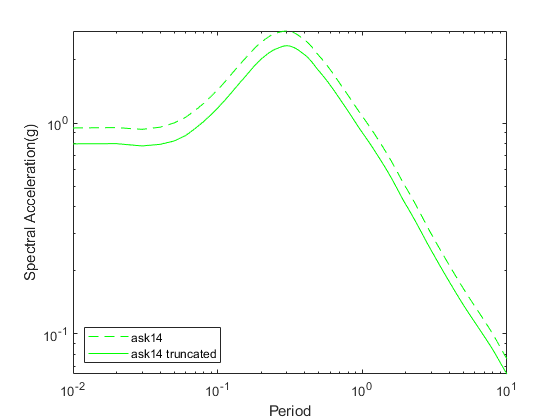

xq = 0.01:0.01:10;

pask14 = pchip(ask14x,ask14y,xq);
pask14t = pchip(ask14x,ask14ty,xq);
loglog(xq,pask14,'--g',xq,pask14t,'-g')
legend('ask14','ask14 truncated','Location','southwest')
ylabel('Spectral Acceleration(g)')
xlabel('Period')

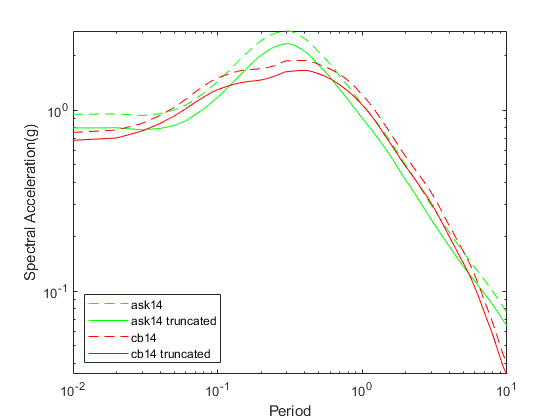


pcb14 = pchip(cb14x,cb14y,xq);
pcb14t = pchip(cb14x,cb14ty,xq);
loglog(xq,pask14,'--g',xq,pask14t,'-g',xq,pcb14,'--r',xq,pcb14t,'-r')
legend('ask14','ask14 truncated','cb14','cb14 truncated','Location','southwest')
ylabel('Spectral Acceleration(g)')
xlabel('Period')

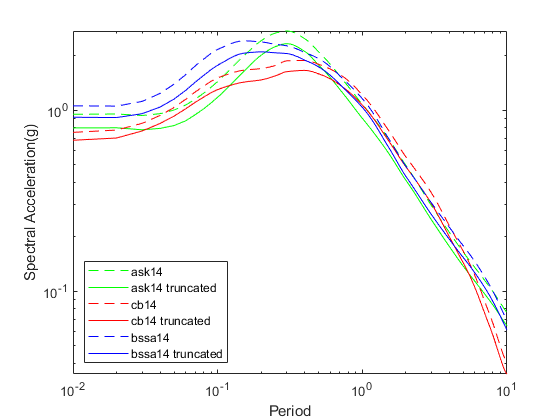


bssa14 = pchip(bssa14x,bssa14y,xq);
bssa14t = pchip(bssa14x,bssa14ty,xq);
loglog(xq,pask14,'--g',xq,pask14t,'-g',xq,pcb14,'--r',xq,pcb14t,'-r',xq,bssa14,'--b',xq,bssa14t,'-b')
legend('ask14','ask14 truncated','cb14','cb14 truncated','bssa14','bssa14 truncated','Location','southwest')
ylabel('Spectral Acceleration(g)')
xlabel('Period')

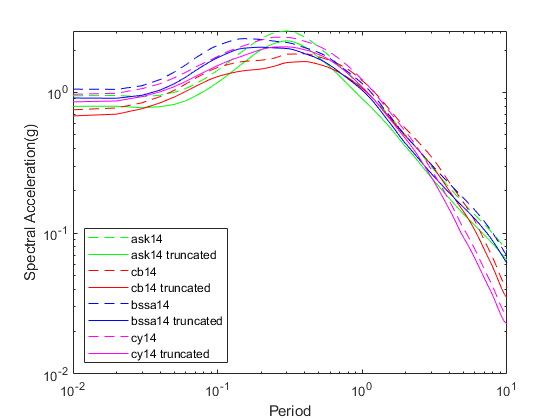


cy14 = pchip(cy14x,cy14y,xq);
cy14t = pchip(cy14x,cy14ty,xq);
loglog(xq,pask14,'--g',xq,pask14t,'-g',xq,pcb14,'--r',xq,pcb14t,'-r',xq,bssa14,'--b',xq,bssa14t,'-b',xq,cy14,'--m',xq,cy14t,'-m')
legend('ask14','ask14 truncated','cb14','cb14 truncated','bssa14','bssa14 truncated','cy14','cy14 truncated','Location','southwest')
ylabel('Spectral Acceleration(g)')
xlabel('Period')

#### Uniform hazard spectra for the four GMMs

uhs = zeros(1000,1);
for i= 1 : 1 : 1000
    weight = 0.25*0.7.*pask14(i) + ...
        0.25*0.3.*pask14t(i) + ...
        0.25*0.7.*pcb14(i) + ...
        0.25*0.3.*pcb14t(i) + ...
        0.25*0.7.*bssa14(i) + ...
        0.25*0.3.*bssa14t(i) + ...
        0.25*0.7.*cy14(i) + ...
        0.25*0.3.*cy14t(i);
    uhs(i) = weight;
end

#### Average of Response Spectra Curves data

ars = zeros(1000,1);
for i= 1 : 1 : 1000
    aaver = (pask14(i)+pask14t(i)+pcb14(i)+pcb14t(i)+bssa14(i)+bssa14t(i)+cy14(i)+cy14t(i)) / 8 ;
    ars(i) = aaver;
end


$${<\mu_x >}_{0\ldotp 95} =\left\lbrack \bar{x} \pm \;t_{p\;=0\ldotp 95,f=3} *\frac{\sigma_x }{\sqrt{n}}\right\rbrack$$


calculate $\frac{\sigma_x }{\sqrt{n}}$

stttdd = zeros(1000,1);
for i= 1 : 1 : 1000
    stttd = [pask14(i), pask14t(i), pcb14(i), pcb14t(i),bssa14(i), bssa14t(i),cy14(i), cy14t(i)];
    stttdd(i) = std(stttd)/(sqrt(8));
end


$$t_{p\;=0\ldotp 95,f=7}$$


t = 1.895;


$$\bar{x} +t_{p\;=0\ldotp 95,f=7} *\frac{\sigma_x }{\sqrt{n}}$$


minter = zeros(1000,1);
for i= 1 : 1 : 1000
    minter(i) = ars(i) + t*stttdd(i);
end


$$\bar{x} -t_{p\;=0\ldotp 95,f=7} *\frac{\sigma_x }{\sqrt{n}}$$


pinter = zeros(51,1);
for i= 1 : 1 : 1000
    pinter(i) = ars(i) - t*stttdd(i);
end

#### Plot graph

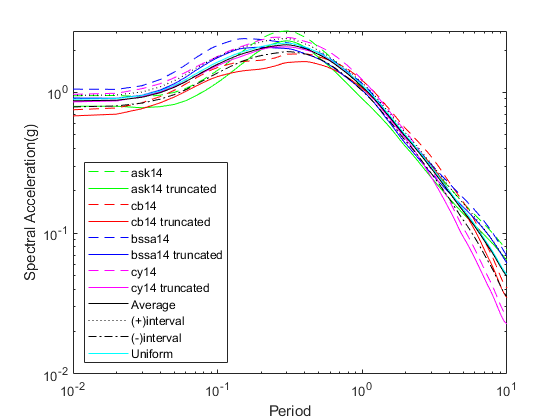

loglog(xq,pask14,'--g',xq,pask14t,'-g',xq,pcb14,'--r',xq,pcb14t,'-r',xq,bssa14,'--b',xq,bssa14t,'-b',xq,cy14,'--m',xq,cy14t,'-m',xq,ars,'k',xq,minter,':k',xq,pinter,'-.k',xq,uhs,'c')
ylabel('Spectral Acceleration(g)')
xlabel('Period')
legend('ask14','ask14 truncated','cb14','cb14 truncated','bssa14','bssa14 truncated','cy14','cy14 truncated','Average','(+)interval','(-)interval','Uniform','Location','southwest')

% legend('Average','(+)interval','(-)interval')